## `Table of Contents`

- Overview

- Model Inputs

- Driving Scenario Creation

- Reference Path Creation

- Additional inputs

## `Overview`

        This script aims to control the steering angle and velocity of a vehicle to follow the optimized path. This simulation will be shown in XY plotter and Unreal engine. This will be done by importing the optimum path and velocity. Then a driving scenario and a reference path will be created based on the optimization results. The scenario will be fed to a Simulink model which will force a the 3 DOF vehicle to follow the optimum path and simulate the result accordingly. Finally, the vehicle parameters will be estimated to find the optimum ones. All these procedures will be explained below.

## `Model Inputs`

        The Simulink model need several inputs related to the vehicle, environment which are as follows:

- Vehicle Mass in kg (mass)

- Vehicle wheelbase in meters (wheelbase) which is the distance between the centers of the front and rear wheels

- Center of gravity location from the front wheels in meters (dfront)

-  Center of gravity location from the rear wheels in meters (drear)

- Vehicle axle height in meters (h)

- Front tire Corner Stiffness in N/rad (FrontCornerStiffness) which is the ability of the tire to resist shape deformation while the vehicle corners

- Rear tire Corner Stiffness in N/rad (RearCornerStiffness) 

- Coefficient of Friction (mu) between the tires and the ground

- Steering Agressiveness (aggressive) which is a lateral controller parameter that ranges between 0 and 1 (0 is for more robust steering and 1 is for more agressive steering) 

- Max steering angle in rad (max_steer) which is a lateral controller parameter that control the maximum steering angle the vehicle can turn

- Min steering angle in rad (min_steer) which is a lateral controller parameter that control the minimum steering angle the vehicle can turn

- Prediction Horizon in steps (pred_Horizon) which is a lateral controller parameter that measures how many steps ahead the controller will predict the track curvature 

- Frontal Area in m^2 (FrontalArea) which is the area affected by the drag force

- Track Width in meters (TrackWidth) which is the distance between two wheels on the same axle

- Drag Coefficient (DragCoefficient) which is a coefficient to quantify the air resistance

- Pitch/Roll/Yaw Moment of Inertia in kg.m^2 (PitchMomentinertia/ RollMomentinertia/ YawMomentinertia)

        Parameters 13 to 16 are saved in a structure named VEH

    % 1. Vehicle mass
        mass = 2500

mass = 2500

    % 2. Wheelbase
        wheelbase = 2.8

wheelbase = 2.8000

    % 3. Center of gravity location from the front wheels
        dfront = 1.2

dfront = 1.2000

    % 4. Center of gravity location from the rear wheels
        drear=wheelbase-dfront

drear = 1.6000

    % 5. Height of the vehicle axle
        h = 0.35

h = 0.3500

    % 6. Front tire Corner Stiffness
        f_tire_stiff= 40000

f_tire_stiff = 40000

    % 7. Front tire Corner Stiffness
        r_tire_stiff= 40000

r_tire_stiff = 40000

    % 8. Coefficient of Friction
        mu = 1

mu = 1

    % 9. Steering Agressiveness 
        aggressive= 0.2

aggressive = 0.2000

    % 10. Max steering angle in rad
        max_steer= 0.19

max_steer = 0.1900

    % 11. Min steering angle in rad
        min_steer= -0.19

min_steer = -0.1900

    % 12. Controller Prediction Horizon
        pred_Horizon= 10

pred_Horizon = 10

    % 13. Load Vehicle Parameter File
        load('VEH.mat')
        VEH   

VEH = struct with fields:
           FrontalArea: 2
       DragCoefficient: 0.3300
    PitchMomentInertia: 1.9227e+03
     RollMomentInertia: 432.3333
      YawMomentInertia: 2066
            TrackWidth: 2.1100


Moreover, additional inputs are needed for the simulation such as:

- The optimization results which are saved in a mat file

- Sampling Time in seconds (Ts) which is the time interval between the simulation steps

    % 1. Name of the mat file that contains the
    % optimization info
        FileName='Controller_test'

FileName = 'Controller_test'

    % 2. Sampling time
        Ts=0.1

Ts = 0.1000

 The File name will be fed to "extractTheData" function which will extract the x and y coordinates and the vehicle velocity.

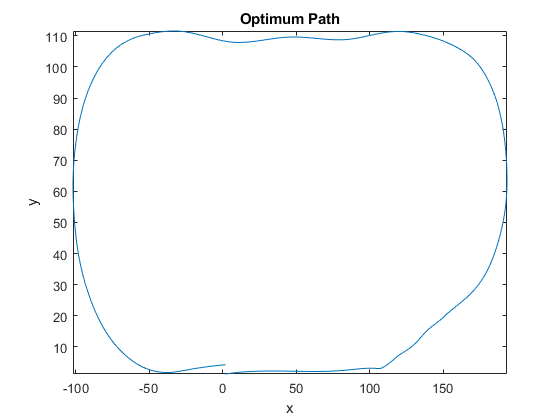

%% Extract the data (path coordinates and speed profile)
% from the mat file
[x,y,speedProfile] = extractTheData(FileName);
plot(y,x)
xlabel("x")
ylabel("y")
title("Optimum Path")
axis tight

plot(speedProfile)
xlabel("Time (s)")
ylabel("Speed (m/s)")
title("Speed Profile")
axis tight

## `Driving Scenario Creation`

    The drivingScenario object represents a driving test case to model realistic scenarios and to generate synthetic detections for testing controllers. It can be created using Driving Scenario Designer app or using MATLAB.

         In this example, the Sampling time (Ts), optimized path (x,y coordinates) and velocity (speedProfile) will be fed to the 'createDrivingScenario' function to get the drivingScenario object (scenario), the vehicle object (egoVehicle) and the sampled track (waypoints).

        The Driving Scenario object is used in this example to get some of the Simulink model inputs such as:

- Path curvature (derived from Lane Detections)

- Lateral deviation from the desired path (derived from Lane Detections)

- Vehicle yaw angle and relative yaw angle (derived from Lane Detections)

%% Driving Senario Creation
[scenario, egoVehicle,waypoints]= createDrivingScenario ...
(x,y,Ts,speedProfile);

## `Reference Path Creation`

    The objective of the 'helperCreateReferencePath' function is extract the sampled vehicle initial and reference position, vehicle speed vector and path curvature by advancing the scenario step by step and save the desired outputs. All of these outputs will be used in the Simulink model.

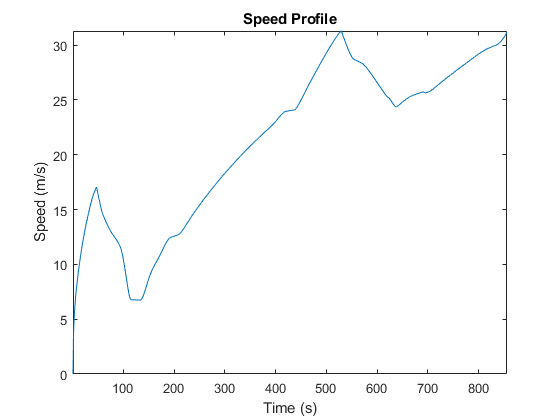

%% Reference Path Creation
[refPoses, x0, y0, theta0, simStopTime,speedVector ...
    ,curvatures]= helperCreateReferencePath(scenario);

simStopTime=43;

## `Additional inputs`

    Finally,the velocity magnitude is found from the velocity vector and direction of the vehicle motion is defined where 1 refers to forward motion and -1 refers to reverse motion.

%% Additional variables needed for the simulation
% Find the velocity magnitude
speedProfile  = sqrt(sum(speedVector.*speedVector,2));
% Specify the motion direction
directions=ones(size(speedProfile));